For regression:

- **MSE (Mean Squared Error)**: This is the average of the squared differences between the predicted and actual values. A lower MSE indicates a better model fit.

- **RMSE (Root Mean Squared Error)**: This is the square root of MSE. It is in the same units as the dependent variable, which helps in understanding the error magnitude.

- **MAE (Mean Absolute Error)**: This gives the average absolute difference between the predicted and actual values.

Below code plots a graph based on actual metrics

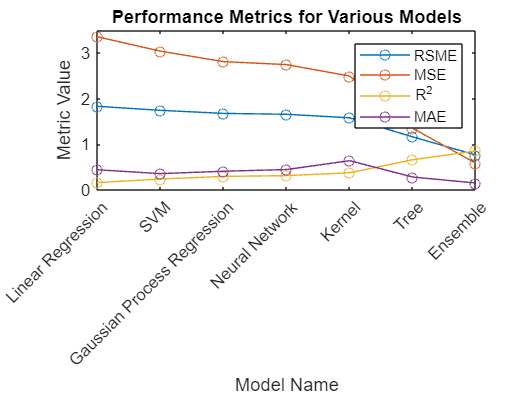

% Define the data
models = {'Linear Regression', 'SVM', 'Gaussian Process Regression', ...
          'Neural Network', 'Kernel', 'Tree', 'Ensemble'};

RSME = [1.83134851, 1.743239226, 1.675689501, 1.656310822, 1.578865435, 1.16132531, 0.763940205];
MSE = [3.353837365, 3.038882999, 2.807935304, 2.743365538, 2.492816063, 1.348676476, 0.583604637];
r2 = [0.161612063, 0.240343949, 0.298075956, 0.314217023, 0.376849057, 0.662823313, 0.854095566];
MAE = [0.443402127, 0.358141124, 0.41002344, 0.44750128, 0.641419742, 0.283147708, 0.152779843];

% Create a single line plot
figure;

plot(1:numel(models), RSME, '-o', 'DisplayName', 'RSME');
hold on;
plot(1:numel(models), MSE, '-o', 'DisplayName', 'MSE');
plot(1:numel(models), r2, '-o', 'DisplayName', 'R^2');
plot(1:numel(models), MAE, '-o', 'DisplayName', 'MAE');

% Add details
xticks(1:numel(models));
xticklabels(models);
xtickangle(45);
xlabel('Model Name');
ylabel('Metric Value');
legend('show');
title('Performance Metrics for Various Models');

hold off;

The concept of "accuracy" in percentage is typically associated with classification models.

However for regression we can calculate the relative accuracy based on the following metrics. 


$$\text {Relative Accuracy of RSME}= 100*(1-\frac{RSME}{RSME_{max}})$$



$$\text {Relative Accuracy MSE}= 100*(1-\frac{MSE}{MSE_{max}})
$$



$$\text{Relative accuracy of } R^2 = R^2 * 100$$



$$\text {Relative Accuracy MAE}= 100*(1-\frac{MAE}{MAE_{max}})
$$


Below code plots the relative accuracy of each model

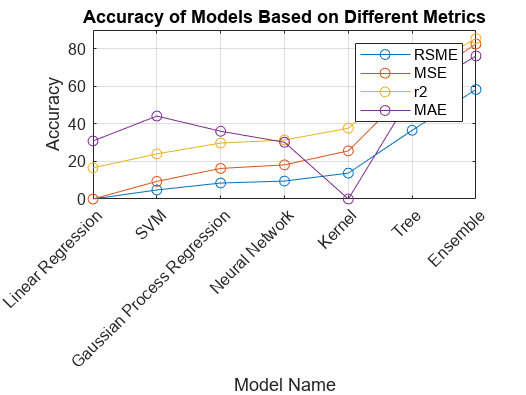

% Define the data
models = {'Linear Regression', 'SVM', 'Gaussian Process Regression', ...
          'Neural Network', 'Kernel', 'Tree', 'Ensemble'};
RSME = [0, 4.81, 8.5, 9.55, 13.79, 36.6, 58.3];
MSE = [0, 9.38, 16.28, 18.17, 25.64, 59.79, 82.6];
r2 = [16.6, 24.03, 29.81, 31.42, 37.68, 66.28, 85.41];
MAE = [30.91, 44.18, 36.08, 30.22, 0, 55.85, 76.18];

% Plot the data
figure;

plot(RSME, '-o', 'DisplayName', 'RSME');
hold on;
plot(MSE, '-o', 'DisplayName', 'MSE');
plot(r2, '-o', 'DisplayName', 'r2');
plot(MAE, '-o', 'DisplayName', 'MAE');

% Add details
legend('show');
xlabel('Model Name');
ylabel('Accuracy');
title('Accuracy of Models Based on Different Metrics');
set(gca, 'XTickLabel', models, 'XTick', 1:numel(models));
xtickangle(45);  % Rotate the x-axis labels for better visibility
grid on;

hold off;

Now total average relative accuracy of each model is calculated by


$$\text{Total Relative Accuracy} = \frac{\text{Relative Accuracy of }\text{(RSME + MSE + MAE+}R^2)}{4}$$


Below code plots the Total Relative Accuracy with respect to RSME

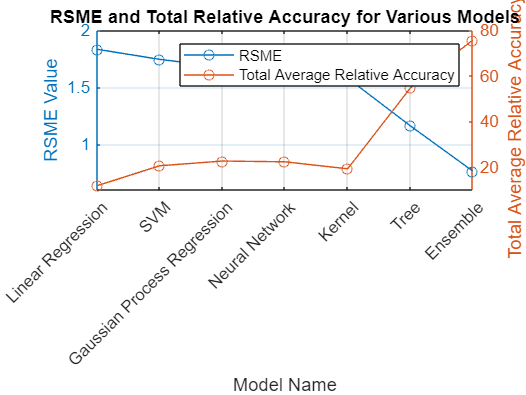

% Define the data
models = {'Linear Regression', 'SVM', 'Gaussian Process Regression', ...
          'Neural Network', 'Kernel', 'Tree', 'Ensemble'};

RSME = [1.83134851, 1.743239226, 1.675689501, 1.656310822, 1.578865435, 1.16132531, 0.763940205];
Total_Average_Relative_Accuracy = [11.87775, 20.6, 22.6675, 22.34, 19.2775, 54.63, 75.6225];

% Plot the data
figure;

yyaxis left;
plot(RSME, '-o', 'DisplayName', 'RSME');
ylabel('RSME Value');
xlabel('Model Name');

yyaxis right;
plot(Total_Average_Relative_Accuracy, '-o', 'DisplayName', 'Total Average Relative Accuracy');
ylabel('Total Average Relative Accuracy (%)');
legend('show');

% Add details
title('RSME and Total Relative Accuracy for Various Models');
set(gca, 'XTickLabel', models, 'XTick', 1:numel(models));
xtickangle(45);
grid on;

The below code plots the true yield vs predicted yield in rice production

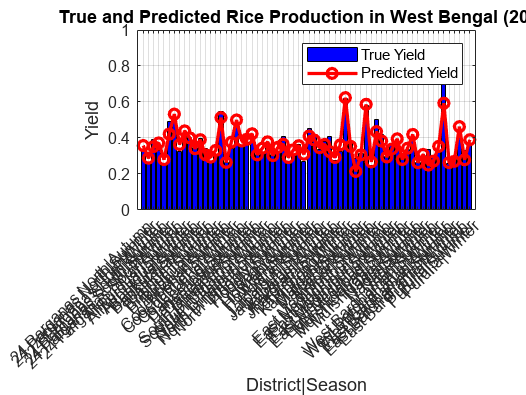

%% Import data from spreadsheet
% Script for importing data from the following spreadsheet:
%
%    Workbook: C:\Users\ds10u\Desktop\Accuracy\Copy of Book1.xlsx
%    Worksheet: Sheet1
%
% Auto-generated by MATLAB on 15-Sep-2023 14:52:48

%% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 6);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:F65";

% Specify column names and types
opts.VariableNames = ["DISTRICT", "SEASON", "Var3", "Var4", "TrueYield", "FalseYield"];
opts.SelectedVariableNames = ["DISTRICT", "SEASON", "TrueYield", "FalseYield"];
opts.VariableTypes = ["string", "string", "char", "char", "double", "double"];

% Specify file level properties
opts.ImportErrorRule = "omitrow";
opts.MissingRule = "omitrow";

% Specify variable properties
opts = setvaropts(opts, ["DISTRICT", "SEASON", "Var3", "Var4"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["DISTRICT", "SEASON", "Var3", "Var4"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, ["TrueYield", "FalseYield"], "TreatAsMissing", '');

% Import the data
CopyofBook1 = readtable("C:\Users\DELL\Desktop\Accuracy\Accuracy\Copy of Book1.xlsx", opts, "UseExcel", false);


%% Clear temporary variables
clear opts
% Assuming your table is loaded as 'CopyofBook1'

% Create a new column by merging the "District" and "Season" columns
CopyofBook1.MergedColumn = strcat(CopyofBook1.DISTRICT, "|", CopyofBook1.SEASON);

% Extract data
mergedDistrictsSeasons = CopyofBook1.MergedColumn;
% Convert merged strings to categorical
mergedDistrictSeasons = categorical(CopyofBook1.MergedColumn);
trueYield = CopyofBook1.TrueYield;
predictedYield = CopyofBook1.FalseYield;  % Note: Changed from 'FalseYield'. Make sure this column name is correct.

% Create the figure
figure;

% Plot true yield as a histogram (bar graph)
bar(trueYield, 'FaceColor', [0, 0, 1], 'DisplayName', 'True Yield');

hold on;

% Plot predicted yield as a line graph on top of the bar graph
plot(predictedYield, '-o', 'LineWidth', 2, 'Color', 'r', 'DisplayName', 'Predicted Yield');

% Add labels and title
xlabel('District|Season');
ylabel('Yield');
title('True and Predicted Rice Production in West Bengal (2019)');

% Set x-ticks and their labels
set(gca, 'XTick', 1:numel(mergedDistrictSeasons), 'XTickLabel', cellstr(mergedDistrictSeasons));

% Rotate x-axis labels for better visibility
xtickangle(45);

% Add legend
legend;

% Adjust figure properties for better layout
set(gca, 'FontSize', 10);
grid on;

hold off;

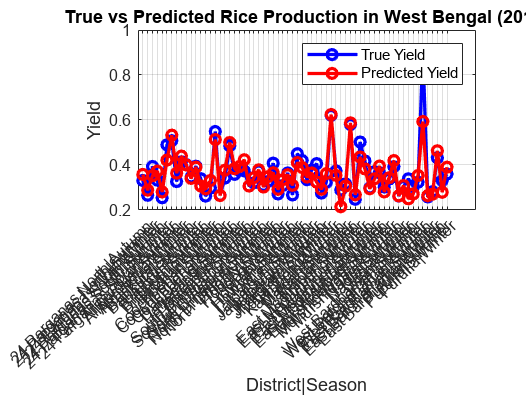

% ... [previous code here]

% Create a new figure for the overlapped line plots
figure;

% Plot true yield as a line graph
plot(trueYield, '-o', 'LineWidth', 2, 'Color', 'b', 'DisplayName', 'True Yield');

hold on;

% Plot predicted yield as an overlapped line graph
plot(predictedYield, '-o', 'LineWidth', 2, 'Color', 'r', 'DisplayName', 'Predicted Yield');

% Add labels, title, and legend
xlabel('District|Season');
ylabel('Yield');
title('True vs Predicted Rice Production in West Bengal (2019)');
legend;

% Set x-ticks and their labels
set(gca, 'XTick', 1:numel(mergedDistrictSeasons), 'XTickLabel', cellstr(mergedDistrictSeasons));
xtickangle(45);

% Adjust figure properties for better layout
set(gca, 'FontSize', 10);
grid on;

hold off;